clear;
mf = 0.546;
If = 0.0067;
Lf = 0.0958;
Bf = 0.0036;
mw = 0.220;
Iw = 0.699E-3;
Lw = 0.092;
Bw = 1.93E-5;
M  = 33.5E-3;
La = 0.572E-3;
Ra = 1.03;
g  = 9.816;

Ka = 1.1685;
Km = 107.47;
kt = 33.5e-3;
% --------------- Constants ---------------
a1 = Lf^2*mw+If;
a2 = g*(mw*Lf+mf*Lw);
% -----------------------------------------

a11 = 0;
a12 = 1;
a13 = 0;
a21 = a2/(-Iw+a1);
a22 = (-Bf)/(-Iw+a1);
a23 = Bw/(-Iw+a1);
a31 = a2/(Iw-a1);
a32 = (-Bf)/(Iw-a1);
a33 = (Bw*a1)/((Iw-a1)*Iw);

b1 = 0;
b2 = (-1)/(-Iw+a1);
b3 = (-a1)/((Iw-a1)*Iw);

A =[a11 a12  a13;
    a21  a22  a23;
    a31  a32  a33];
B=[b1
   b2
   b3];
C = [1 0 0];
[P] = eig(A);
sys = ss(A,B,C,0);
eig(A)

ans =    -9.5705
    9.1192
   -0.0276


zero(sys)


## PZ plot SS-model

% hold on;
% line_colors = [0 0 0; 0.6 0.6 0.6]; % Black and grey (RGB)
% set(gca, 'ColorOrder', line_colors);
% pzmap(sys,'k');
% title("Pole-Zero Plot",FontName="Palatino Linotype",FontSize=12);
% ylabel("Imaginary Axis",FontName="Palatino Linotype",FontSize=11);
% xlabel("Real Axis",FontName="Palatino Linotype",FontSize=11)
% f = gcf;
% ylim([-1 1]);
% xlim([-10 10]);
% hold off;
% exportgraphics(f,'PoleZeroPlot_ss.pdf')

## finding Q matrix

 e11 = (10/180*pi) % deg

e11 = 0.1745

 e22 = (150/180*pi)^2 % 150deg/s

e22 = 6.8539

 e33 = (548)^2 %nominal motor speed

e33 = 300304

ans = 3.3300e-06

Q = [1/e11 0 0;
    0 1/e22 0;
    0 0 1/e33]

Q =     5.7296         0         0
         0    0.1459         0
         0         0    0.0000


## finding R matrix

emotor = (83*10^-3)^2 %max motor torque

emotor = 0.0069

R=1/emotor

R = 145.1589

[K]=lqr(sys,Q,R,0)

K =    -1.4609   -0.1546   -0.0002


sysLQR = ss(A-B*K,B,C,0);

## LQR Plot

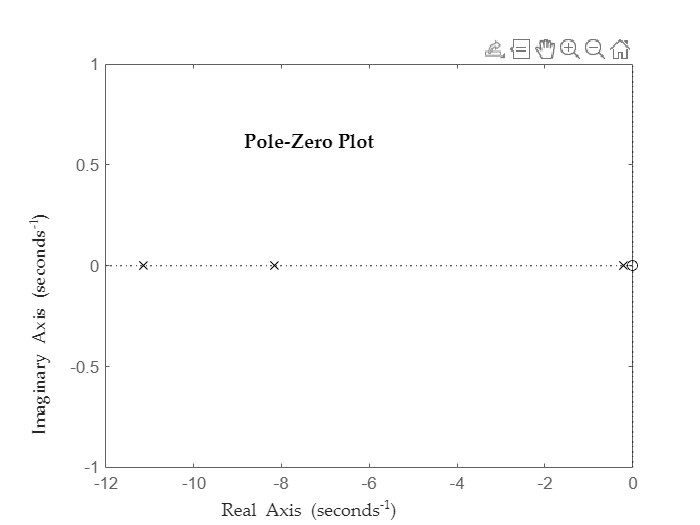

hold on;
line_colors = [0 0 0; 0.6 0.6 0.6]; % Black and grey (RGB)
set(gca, 'ColorOrder', line_colors);
pzmap(sysLQR,'k')
title("Pole-Zero Plot",FontName="Palatino Linotype",FontSize=12);
ylabel("Imaginary Axis",FontName="Palatino Linotype",FontSize=11);
xlabel("Real Axis",FontName="Palatino Linotype",FontSize=11)
f = gcf;
ylim([-1 1]);
hold off;
exportgraphics(f,'PoleZeroPlot_LQR.pdf')